# Report Title & Date

## Descrption 

Description of testing, notes, etc

clear all; close all; clc;
s = settings;
s.matlab.editor.language.matlab.comments.MaxWidth.TemporaryValue = 80;
s.matlab.editor.export.pdf.FigureFormat.TemporaryValue = 'png';
s.matlab.editor.export.pdf.FigureResolution.TemporaryValue = 800;
s.matlab.editor.export.pagesetup.pdf.PaperSize.TemporaryValue = 'Letter';
s.matlab.editor.export.pagesetup.pdf.Margins.TemporaryValue = [20 28 28 20];

#### File Paths

dataFilesPath = "..\..\PSU_Normal_Impedance_Tube\ExampleData\";
processScriptPath = "..\..\PSU_Normal_Impedance_Tube\ProcessData\ProcessDataNIT_ASTM_E1050.mlx";
outputPath = "..\..\PSU_Normal_Impedance_Tube\ExampleOutputs\";
outputReportName = ["ExampleOutput.pdf","ExampleOutput.html"];
addpath("..\..\PSU_Normal_Impedance_Tube\Functions\")

#### Read All Data

cd(dataFilesPath);
fileInfo = dir('**/*.h5');
fileCount = length(fileInfo);
for n = 1:fileCount
    fileName = fileInfo(n).name;
    Time = h5read(fileName,'/Table1/Ds1-Time');
    Mic1 = h5read(fileName,'/Table1/Ds2-Signal 1');
    Mic2 = h5read(fileName,'/Table1/Ds3-Signal 2');
    df = [Time, Mic1, Mic2];
    assignin('base', strrep(fileName(1:end-3),'-','_'), df); 
end
clearvars Time Mic1 Mic2 df n

#### OASPL Vs. Time Plots

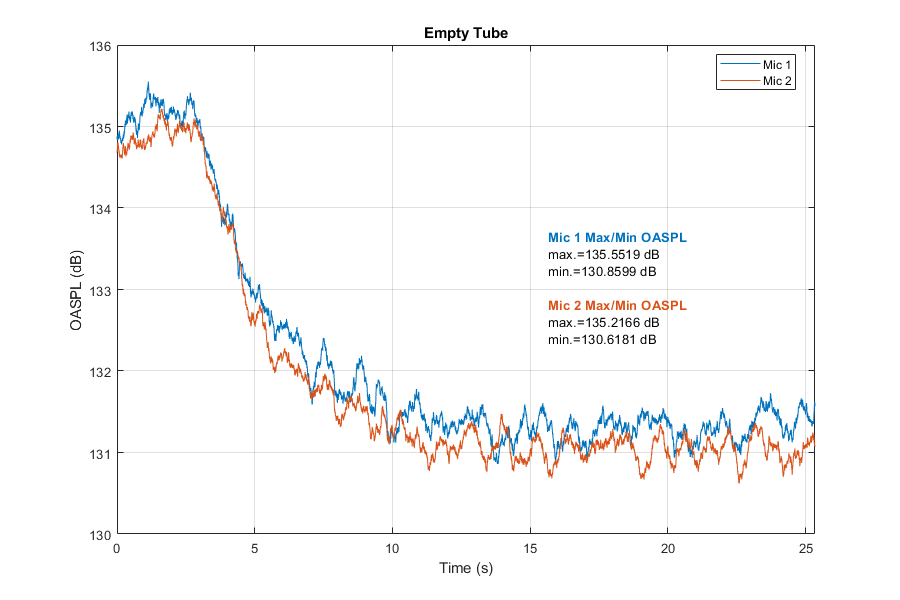

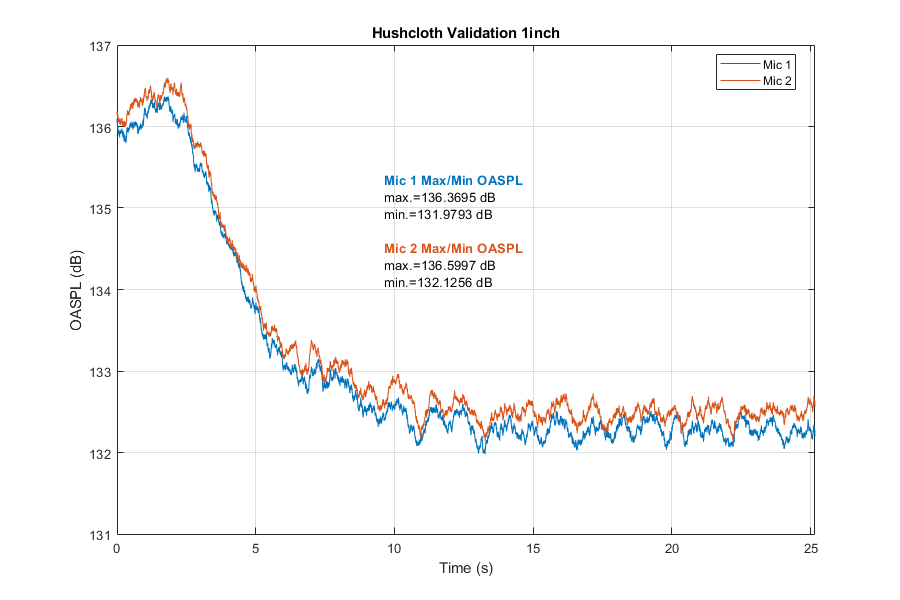

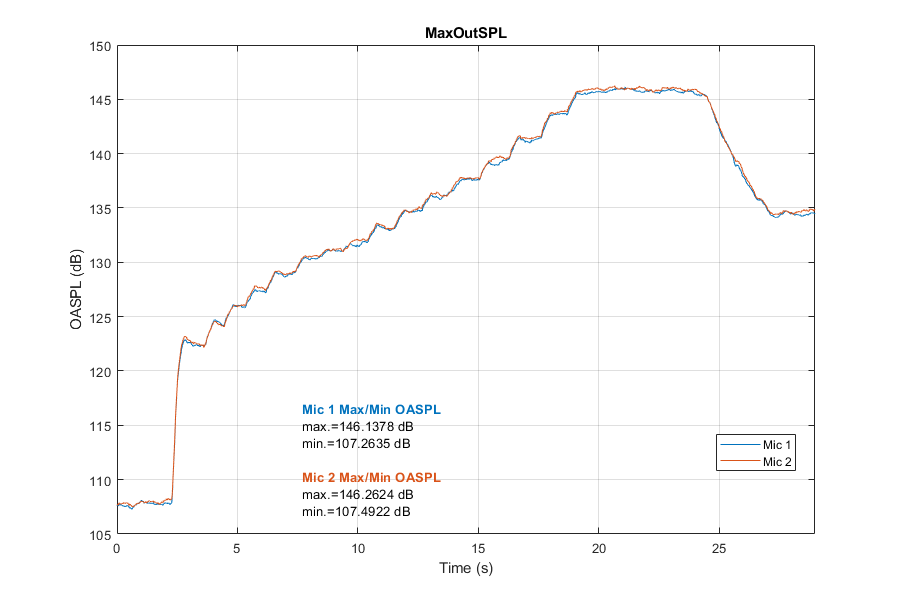

for j = 1:fileCount
    fileName = fileInfo(j).name;
    [SPL_Mic1, SPL_Mic2, Time] = SPLvTimePlot(eval(strrep(fileName(1:end-3),'-','_')));
    figure(j)
    figure('Renderer', 'painters', 'Position', [10 10 900 600]);
    plot1 = plot(Time, SPL_Mic1,'-','LineWidth', 0.5,"color","#0072BD");
    xValue1 = get(plot1,'XData');
    yValue1 = get(plot1,'YData');
    imin1 = find(min(yValue1)==yValue1);
    imax1 = find(max(yValue1)==yValue1);
    hold on
    plot2 = plot(Time, SPL_Mic2,'-','LineWidth', 0.5,"color","#D95319");
    xValue2 = get(plot2,'XData');
    yValue2 = get(plot2,'YData');
    imin2 = find(min(yValue2)==yValue2);
    imax2 = find(max(yValue2)==yValue2);
    xlim([0,max(Time)])
    hold off
    xlabel("Time (s)")
    ylabel("OASPL (dB)")
    title(strrep(strrep(fileName(1:end-3),'-','_'),'_',' '))
    str1 = {'\color[rgb]{0,0.4470,0.7410}Mic 1 Max/Min OASPL'};
    str1{1} = ['\bf',str1{1},'\rm'];
    str2 = {['\color[rgb]{0,0,0}max.=',num2str(yValue1(imax1)),' dB']};
    str3 = {['\color[rgb]{0,0,0}min.=',num2str(yValue1(imin1)),' dB']};
    str4 = {'\color[rgb]{0.8500,0.3250,0.0980}Mic 2 Max/Min OASPL'};
    str4{1} = ['\bf',str4{1},'\rm'];
    str5 = {['\color[rgb]{0,0,0}max.=',num2str(yValue2(imax2)),' dB']};
    str6 = {['\color[rgb]{0,0,0}min.=',num2str(yValue2(imin2)),' dB']};
    textbp([str1,str2,str3," ",str4,str5,str6]);
    legend('Mic 1','Mic 2','location','best');
    grid on
end

#### Absorption Coefficient Vs. Frequency Plots

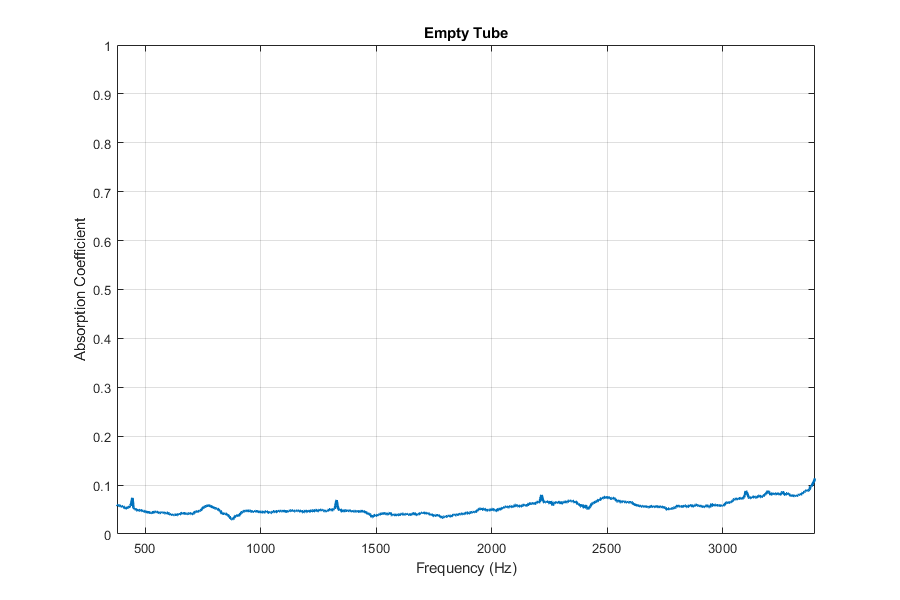

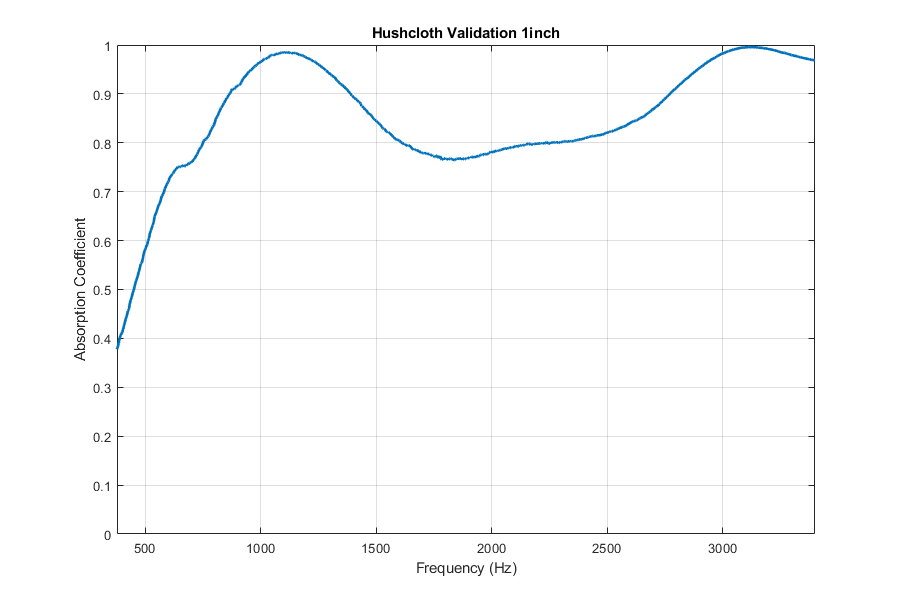

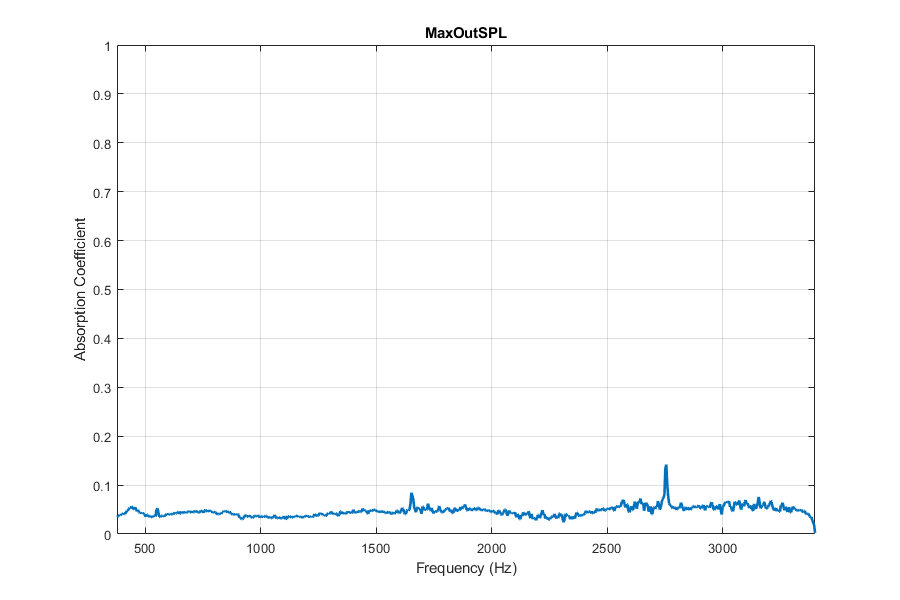

for j = 1:fileCount
    fileName = fileInfo(j).name;
    [alpha, freq] = CalculateNormalIncidenceSoundAbsorptionCoefficient(eval(strrep(fileName(1:end-3),'-','_')));
    figure(j)
    figure('Renderer', 'painters', 'Position', [10 10 900 600]);
    plot(freq,alpha,'LineWidth', 2)
    xlim([377,3.4e3])
    ylim([0,1])
    xlabel("Frequency (Hz)")
    ylabel("Absorption Coefficient")
    title(strrep(strrep(fileName(1:end-3),'-','_'),'_',' '))
    grid on
end

#### Attenuation Vs. Frequency Plots

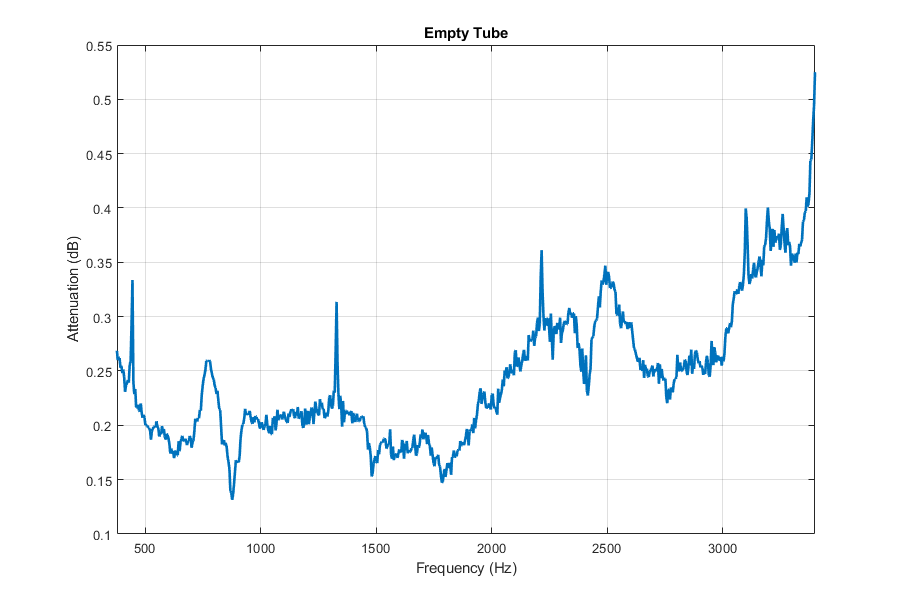

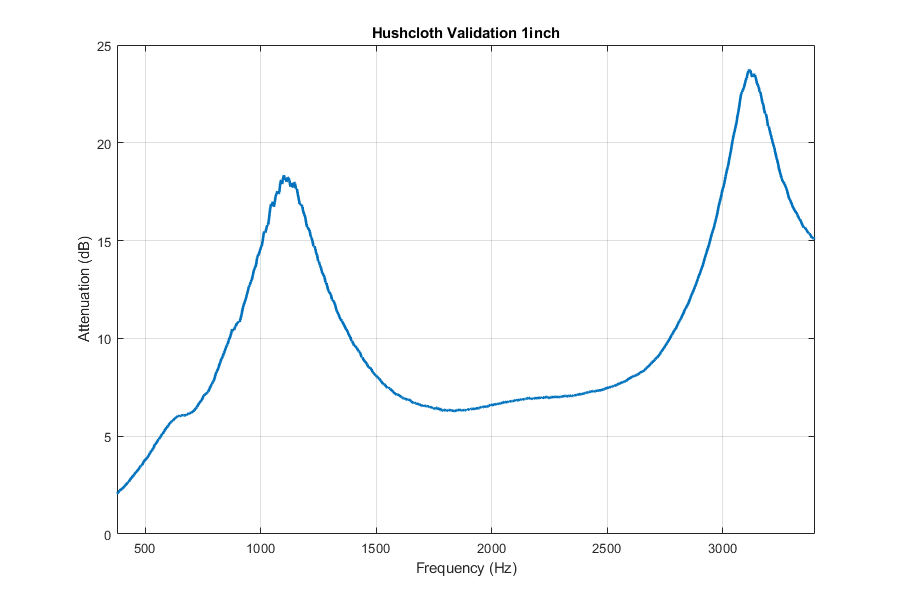

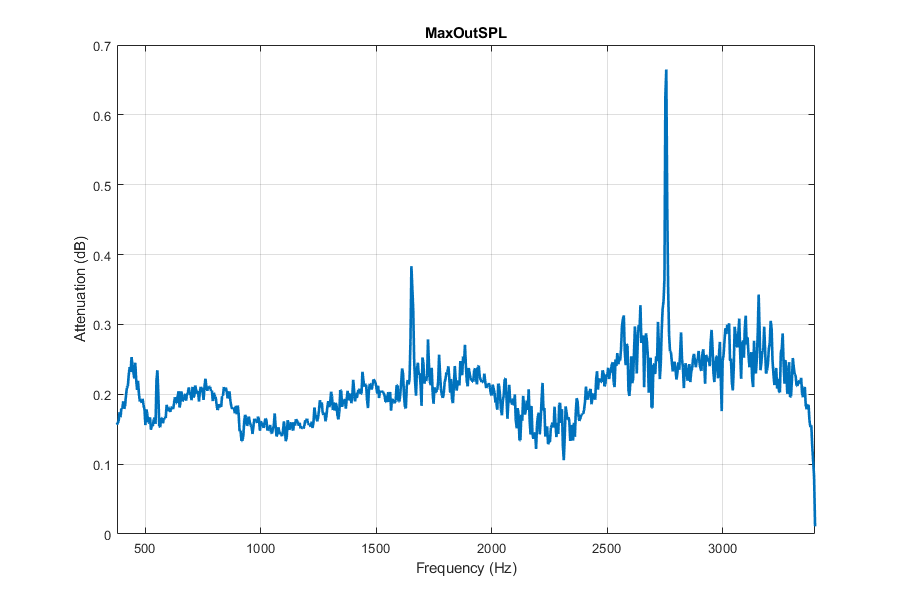

for j = 1:fileCount
    fileName = fileInfo(j).name;
    [aten, freq] = CalculateNormalIncidenceAttenuation(eval(strrep(fileName(1:end-3),'-','_')));
    figure(j)
    figure('Renderer', 'painters', 'Position', [10 10 900 600]);
    plot(freq,aten,'LineWidth', 2)
    xlim([377,3.4e3])
    xlabel("Frequency (Hz)")
    ylabel("Attenuation (dB)")
    title(strrep(strrep(fileName(1:end-3),'-','_'),'_',' '))
    grid on
end

#### Resistance (real component of impedance) Vs. Frequency Plots

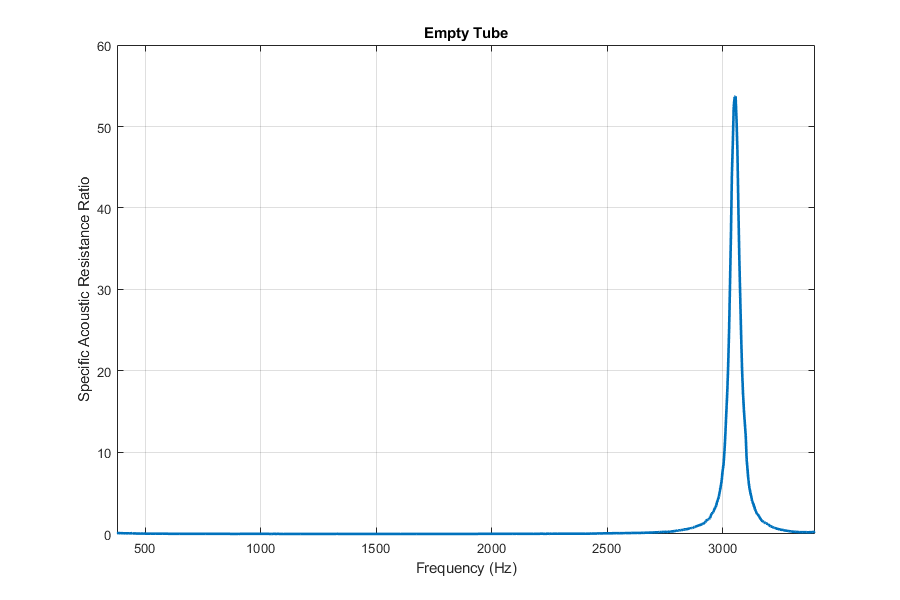

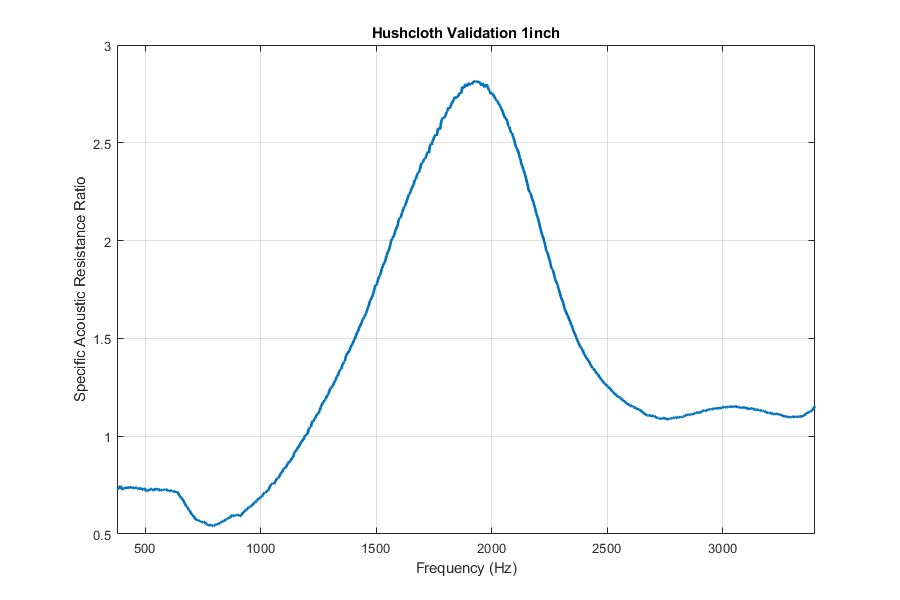

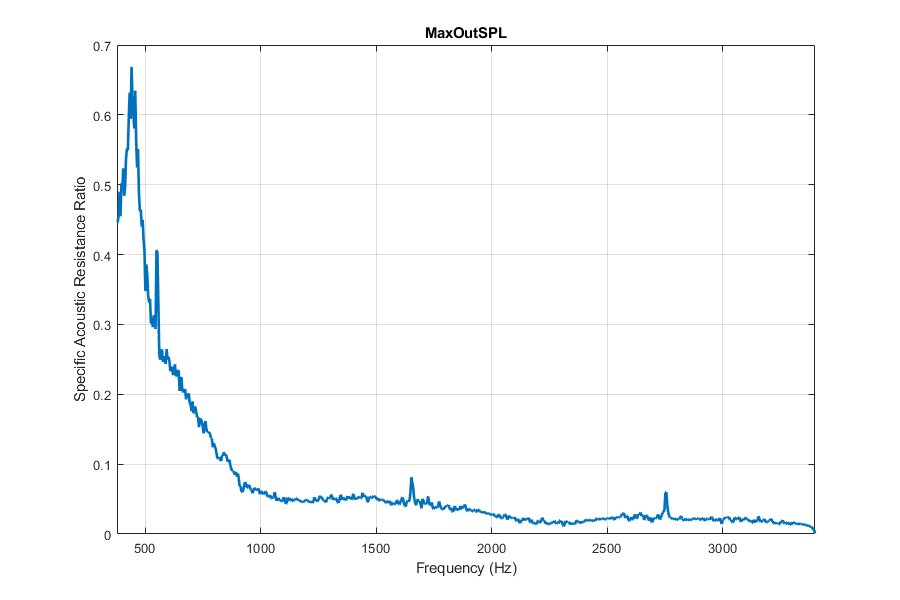

for j = 1:fileCount
    fileName = fileInfo(j).name;
    [z_pc_real, z_pc_imag, freq] = CalculateNormalSpecificAcousticImpedanceRatio(eval(strrep(fileName(1:end-3),'-','_')));
    figure(j)
    figure('Renderer', 'painters', 'Position', [10 10 900 600]);
    plot(freq,z_pc_real,'LineWidth', 2)
    xlim([377,3.4e3])
    xlabel("Frequency (Hz)")
    ylabel("Specific Acoustic Resistance Ratio")
    title(strrep(strrep(fileName(1:end-3),'-','_'),'_',' '))
    grid on
end

#### Reactance (imag component of impedance) Vs. Frequency Plots

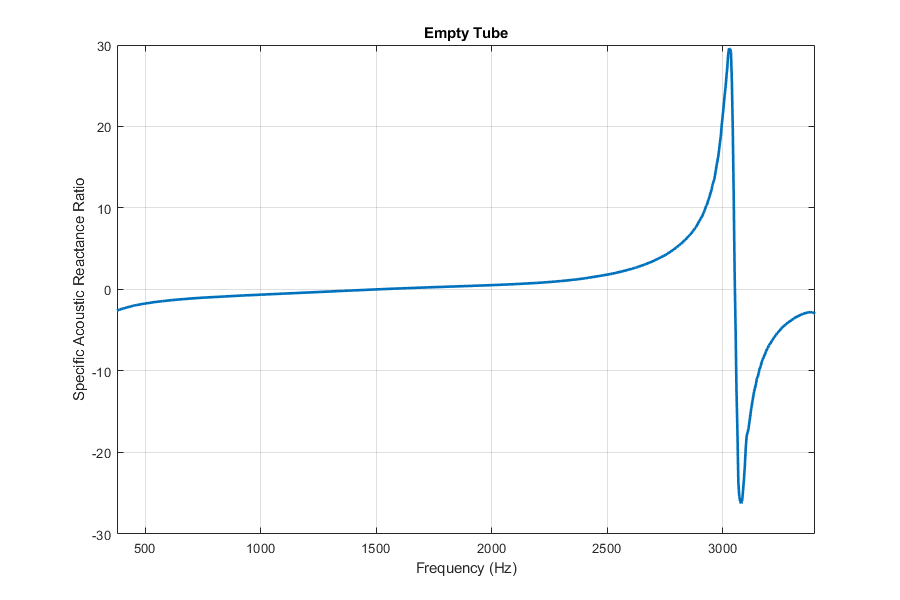

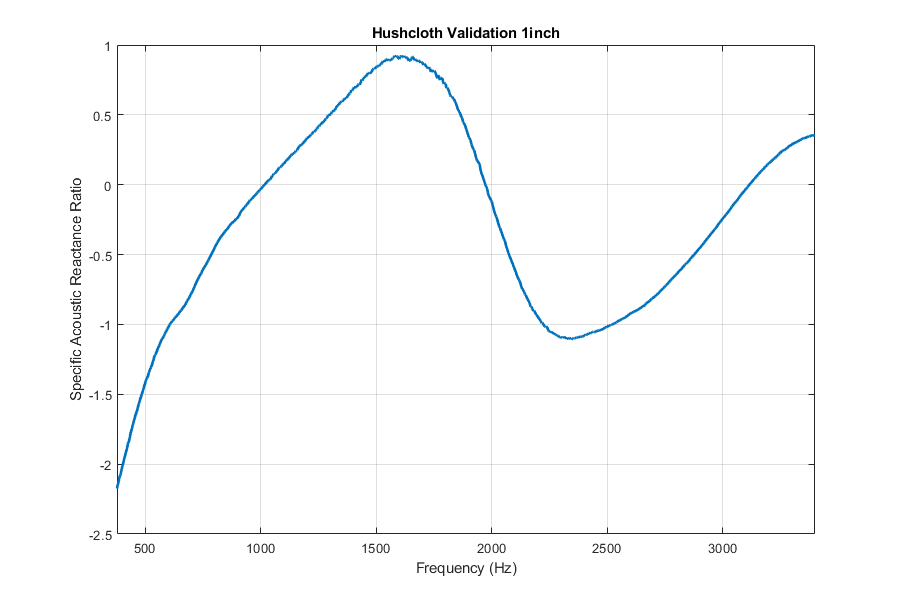

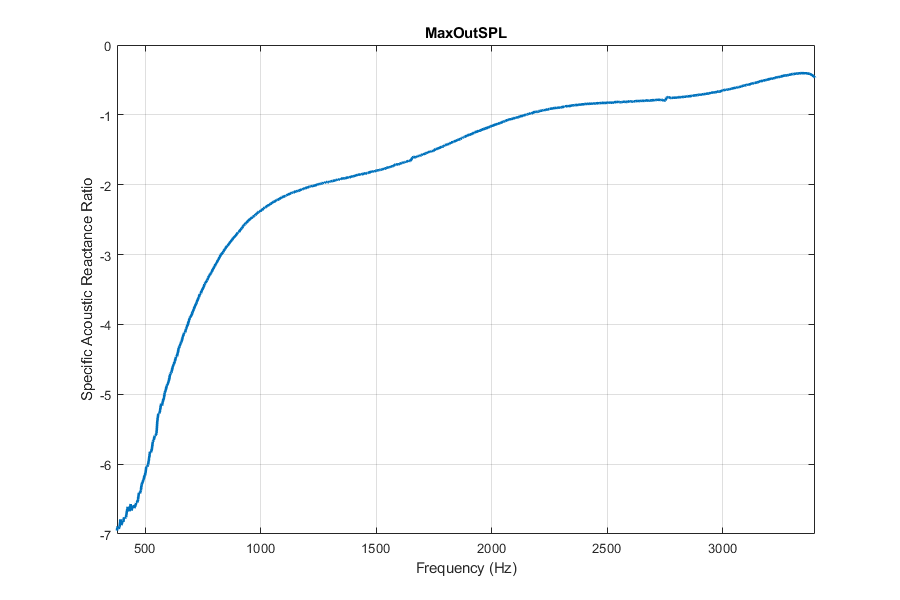

for j = 1:fileCount
    fileName = fileInfo(j).name;
    [z_pc_real, z_pc_imag, freq] = CalculateNormalSpecificAcousticImpedanceRatio(eval(strrep(fileName(1:end-3),'-','_')));
    figure(j)
    figure('Renderer', 'painters', 'Position', [10 10 900 600]);
    plot(freq,z_pc_imag,'LineWidth', 2)
    xlim([377,3.4e3])
    xlabel("Frequency (Hz)")
    ylabel("Specific Acoustic Reactance Ratio")
    title(strrep(strrep(fileName(1:end-3),'-','_'),'_',' '))
    grid on
end

#### Excel Export All Data

for j = 1:fileCount
    fileName = fileInfo(j).name;
    cd(outputPath);
    ExportCSV(eval(strrep(fileName(1:end-3),'-','_')), strrep(fileName(1:end-3),'-','_'));
    cd(dataFilesPath);
end

#### PDF Export

cd(outputPath);
matlab.internal.liveeditor.openAndConvert (convertStringsToChars(processScriptPath),convertStringsToChars(outputReportName(1)), 'HideCode', false);
matlab.internal.liveeditor.openAndConvert (convertStringsToChars(processScriptPath),convertStringsToChars(outputReportName(2)), 'HideCode', false);